# Test correlation between a few different pieces of data

We want to test the hypothesis that length growth of contact fibrils dependence on parameter space is correlated with region II-B dependence on parameter space.

We also want to test the hypothesis that length growth of optical fibrils dependence on parameter space is correlated with optical growth of fibrils and compare to correlation of contact fibril dependence with contact growth.

## Read in Data

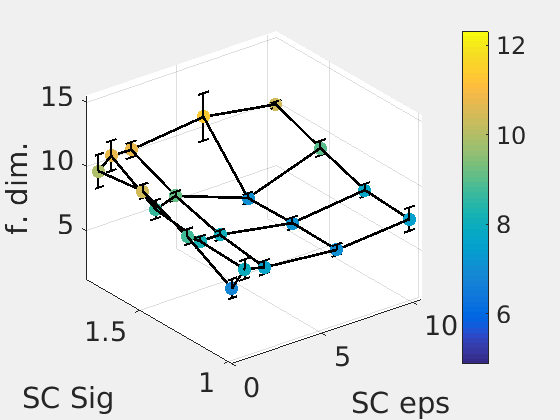

%load rate of growth of size of optical and contact clusters
saveloc = '/home/rachael/coarsegraining/Data/patchy/';
load([saveloc 'tcharsss.mat']);

nstime = 660;
grateO = tcharOsss(:)/nstime;
grateC = tcharCsss(:)/nstime;
%load rate of growth of length of optical and contact clusters
load([saveloc 'fulldistribdata.mat']);

Error using load
Unable to read file '/home/rachael/coarsegraining/Data/patchyfulldistribdata.mat'. No such file or directory.


glrateO = Ollambdas(2:end,:);
glrateC = Cllambdas(2:end,:);
glrateO = glrateO(:);
glrateC = glrateC(:);
%load fractal dimension dependence on parameters (and parameters)
load([saveloc 'fdims.mat']);
params = dims(:);
fdim2b = D2s(:);
fdim2a = D1s(:);

Employ corrcoeff on reshaped stuff.  (Bootstrap comparison? Or just use Matlab p value)?

%is contact fibril lengthening correlated with II-B fractal dimension?
[corrLf2b,pLf2b] = corrcoef(glrateC,fdim2b);
fprintf('C(L,fdim) = %f (p = %f)\n',corrLf2b(1,2),pLf2b(1,2));

C(L,fdim) = 0.879154 (p = 0.000000)


fprintf('C(fdim,L) = %f (p = %f)\n',corrLf2b(2,1),pLf2b(2,1));

C(fdim,L) = 0.879154 (p = 0.000000)



tic
%double-check p-values with a permutation test
iterno = 100000;
len = length(D2s);
cs = zeros(1,iterno);
for i = 1:iterno
    c = corrcoef(glrateC(randperm(len)),fdim2b(randperm(len)));
    cs(i) = c(1,2);
end
p = sum(cs>corrLf2b(1,2))/len;
toc
%is optical fibril lengthening correlated with optical cluster growth?
[corrLO,pLO] = corrcoef(glrateO,grateO);
fprintf('C(LO,gO) = %f (p = %f)\n',corrLO(1,2),pLO(1,2));

C(LO,gO) = 0.708541 (p = 0.000000)


fprintf('C(gO,LO) = %f (p = %f)\n',corrLO(2,1),pLO(2,1));

C(gO,LO) = 0.708541 (p = 0.000000)



%is contact fibril lengthening correlated with contact cluster growth?
[corrLC,pLC] = corrcoef(glrateC,grateC);
fprintf('C(LC,gC) = %f (p = %f)\n',corrLC(1,2),pLC(1,2));

C(LC,gC) = 0.842602 (p = 0.000000)


fprintf('C(gC,LC) = %f (p = %f)\n',corrLC(2,1),pLC(2,1));

C(gC,LC) = 0.842602 (p = 0.000000)


%is contact cluster growth correlated with II-B fractal dimension?
[corrf2b,pf2b] = corrcoef(grateC,fdim2b);
fprintf('C(G,fdim) = %f (p = %f)\n',corrf2b(1,2),pf2b(1,2));

C(G,fdim) = 0.816669 (p = 0.000000)


fprintf('C(fdim,G) = %f (p = %f)\n',corrf2b(2,1),pf2b(2,1));

C(fdim,G) = 0.816669 (p = 0.000000)



%is optical cluster growth correlated with II-A fractal dimension?
[corrf2a,pf2a] = corrcoef(grateO,fdim2a);
fprintf('C(G,fdim) = %f (p = %f)\n',corrf2a(1,2),pf2a(1,2));

C(G,fdim) = -0.466177 (p = 0.000000)


fprintf('C(fdim,G) = %f (p = %f)\n',corrf2a(2,1),pf2a(2,1));

C(fdim,G) = -0.466177 (p = 0.000000)



%what about ratio of cluster growth?
[corrf2arat,pf2arat] = corrcoef(grateO./grateC,fdim2a);
fprintf('C(G,fdim) = %f (p = %f)\n',corrf2arat(1,2),pf2arat(1,2));
fprintf('C(fdim,G) = %f (p = %f)\n',corrf2arat(2,1),pf2arat(2,1));
